# Numerical Methods Assignment 1

Group 11

Noah Labuschagne S6621635

Danail Valov S5609895

Name3 StudentNumber3

**Instructions:**

- Submit the assignment by the deadline on September 16 at 14:00 via Brightspace. All group members must be enrolled in the group before the assignment is submitted.

- Submit two files: this .mlx file and an .pdf export of the same file. Save both files as NM_AS1_GroupX.mlx and NM_AS1_GroupX.pdf, replacing the X by your group number.

- Ensure your group number, names and student numbers are at the top of the document.

- **Consult the course description for details** on the assignment, including information on the discussion and the generative AI policy.

- Include a statement on the ways in which you used generative AI, if any, in the box below. If you worked individually, ensure every group members writes their own statement.

- This type of MATLAB file is called a Live Code File Format (.mlx). It allows you to have all code in one place, and show code, generated figures, text, and equations all next to eachother. It is fairly self-explanatory, but this page and links within it provide some further explanation: [http://nl.mathworks.com/help/matlab/matlab_prog/what-is-a-live-script-or-function.html.](http://nl.mathworks.com/help/matlab/matlab_prog/what-is-a-live-script-or-function.html.) You are welcome to remove the text of the assignment or keep it and add in your solutions. 

## Generative AI statement

*Explain here how you used generative AI, if any, for this assignment. If you worked individually, use a seperate statement for each group member.*

## Set-up *(12 pts.)*

This assignment in on the root-finding methods that are discussed in Chapter 4 of the lecture notes. As you will require an implementation for each other the four methods, start by defining these in the next few blocks of code. The first three tutorials provide instructions on how to implement these functions. Use the stopping criteria suggested during lectures. 

Ensure you are calling the functions you define here in Problems 1-3.

% Implementation of the bisection method
function [root, rootvec] = bisection_method(f, l, u, maxit)
m = ( l + u ) / 2;
it = 1;
rootvec = zeros(1, maxit);

while it <= maxit 
rootvec(it) = m;
prod = f(l) * f(m);
if prod < 0
u = m ;
else
l = m ;
end
m = ( l + u ) / 2; 
it = it + 1; 
end
root = m;
rootvec = rootvec(rootvec ~= 0)

dexact = rootvec(end);
itvec = 0:(length(rootvec)-1);
errvec = abs(rootvec-dexact)/abs(dexact);
figure;
semilogy(itvec,errvec, '.-')
xlabel('Iteration number')
ylabel('Relative error |x_{k}-x^*|/|x^*|')
grid on

end

xvec =     1.0000    0.5000    0.7500    0.6250    0.6875    0.6562    0.6719    0.6797    0.6836    0.6855    0.6865    0.6860    0.6858    0.6859    0.6859


nvec =     1.2500    2.5000    1.6667    2.0000    1.8182    1.9048    1.8605    1.8391    1.8286    1.8234    1.8208    1.8221    1.8227    1.8224    1.8226


dvec =     0.0100    0.0027    0.0059    0.0042    0.0050    0.0046    0.0048    0.0049    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050    0.0050


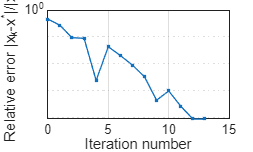

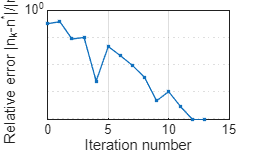

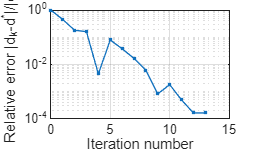

ans =     0.6859    1.8226    0.0050


% Implementation of fixed-point iteration
function [rootFPI, rootvec_FPI] = fixed_point_iteration(g, x0, maxit, tol)

rootvec_sm =     1.2500    1.2500


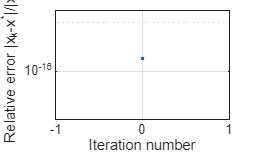

a =     1.2500         0         0


it = 1;
xk = x0;
xk1 = g(xk);
rootvec_FPI = zeros(1, maxit);
while abs((xk1-xk)/xk1) > tol && it < maxit
    rootvec_FPI(it) = xk;
    xk = xk1;
    xk1 = g(xk);
    it = it+1;
end
rootvec_FPI(it) = xk1;
rootFPI = xk1;
rootvec_FPI = rootvec_FPI(rootvec_FPI ~= 0)

dexact = rootvec_FPI(end);
itvec = 0:(length(rootvec_FPI)-1);
errvec = abs(rootvec_FPI-dexact)/abs(dexact);
figure;
semilogy(itvec,errvec, '.-')
xlabel('Iteration number')
ylabel('Relative error |x_{k}-x^*|/|x^*|')
grid on

end

rootvec_sm =     0.5000    5.0000    0.5405    0.5795    1.7007    0.8300    0.9658    1.1099    1.0771    1.0772


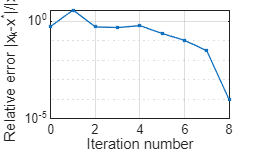

a =     1.2500    1.0772         0


% Implementation of Newton-Raphson

rootvec_sm =     0.5000    0.9091    0.6625    0.6859    0.6859


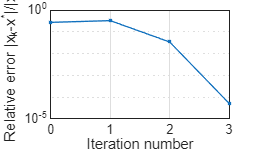

a =     1.2500    1.0772    0.6859


function [root_nrm, rootvec_nrm] = newton_raphson_method(f, f_prime, x0, maxit, tol)
xk = x0;

xk1 = xk - (f(xk)/f_prime(xk));
it = 1;

x = 0.6859

rootvec_nrm2 = zeros(1, maxit);
while abs((xk1-xk)/xk1) > tol && it < maxit
    rootvec_nrm2(it) = xk;
    xk = xk1;
    xk1 = xk - (f(xk)/f_prime(xk));
    it = it + 1;
end
rootvec_nrm(it) = xk1;
root_nrm = xk1;
rootvec_nrm = rootvec_nrm(rootvec_nrm ~= 0)

dexact = rootvec_nrm(end);
itvec = 0:(length(rootvec_nrm)-1);
errvec = abs(rootvec_nrm-dexact)/abs(dexact);
figure;
semilogy(itvec,errvec, '.-')
xlabel('Iteration number')
ylabel('Relative error |x_{k}-x^*|/|x^*|')
grid on
end

% Implementation of the secant method%
function [root_sm, rootvec_sm]= secant_method(f, x0, x1, maxit, tol)
xk = x0;
xk1 = x1;
var1=f(xk);
var2=f(xk1);
xk2 = xk1 - var2*((xk-xk1)/(var1-var2));

h_new = 0.1048

it = 1;
rootvec_sm = zeros(1, maxit+1);

old_area = 0.0050

new_area = 0.0052

while abs((xk2-xk1)/xk2) > tol && it < maxit

percent_increase_in_area = 4.7588

xvec =     1.0000    0.5000    0.7500    0.6250    0.6875    0.6562    0.6719    0.6797    0.6836    0.6855    0.6865    0.6860    0.6858    0.6859    0.6859


nvec =     1.3718    2.7436    1.8291    2.1949    1.9953    2.0904    2.0417    2.0183    2.0067    2.0010    1.9982    1.9996    2.0003    2.0000    2.0001


dvec =     0.0087    0.0024    0.0051    0.0037    0.0044    0.0040    0.0042    0.0043    0.0043    0.0043    0.0044    0.0044    0.0043    0.0043    0.0043


ans =     0.6859    2.0001    0.0043


    rootvec_sm(it) = xk;
    xk = xk1;

    xk1 = xk2;
    var1=var2;
    var2=f(xk1);
    xk2 = xk1 - var2*((xk-xk1)/(var1-var2));
    it = it + 1 ;
end
rootvec_sm(it) = xk1;
rootvec_sm(it+1) = xk2;
root_sm = xk2;
rootvec_sm = rootvec_sm(rootvec_sm ~= 0)

dexact = rootvec_sm(end);
itvec = 0:(length(rootvec_sm)-1);
errvec = abs(rootvec_sm-dexact)/abs(dexact);
figure;
semilogy(itvec,errvec, '.-')
xlabel('Iteration number')
ylabel('Relative error |x_{k}-x^*|/|x^*|')
grid on
end

## Problem 1: Pump operating point and energy consumption *(30 pts.)*

### Problem description

A pumping system transports water from a lower reservoir to an upper reservoir located 8 m higher. The reservoirs are connected by a 500 m-long pipe with an internal diameter of 0.15 m. See below a diagram of the situation:

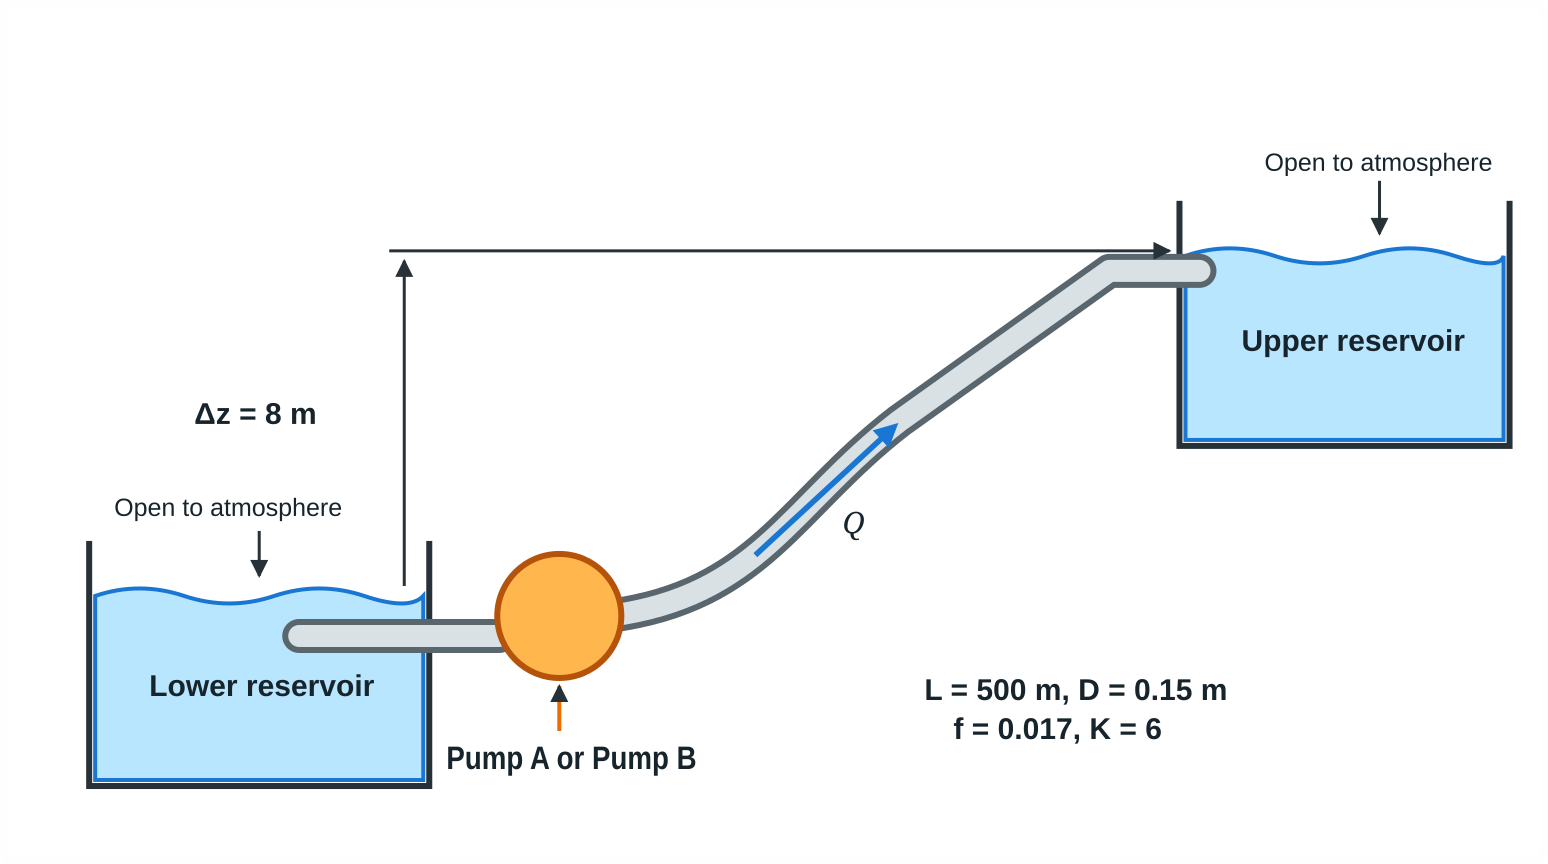

Two pumps are available: pump A and pump B. In this question, you will decide whether you prefer pump A or pump B. We start off by providing all the information necessary for you to answer this question. 

### Pump characteristic curves

The pressure head supplied by each pump $H_{\mathrm{pump}}$ (expressed in m) is represented by the following empirical equation:

$H_{\mathrm{pump}}(Q)
=
H_0-bQ-aQ^2-cQ^3$,

where $Q$ is the volumetric flow rate, expressed in m³/s, $H_0$ is the maximum pressure head produced by the pump when the flow rate is zero. This value is also called the shut-off head. The coefficients $a$, $b$, and $c$ describe how the pump head decreases as the flow rate increases:

• $b$ controls the initial linear decrease in the pump head.

• $a$ represents the quadratic curvature of the pump characteristic curve.

• $c$ captures the stronger nonlinear reduction in pump head at high flow rates.

These coefficients are generally obtained by fitting the polynomial model to experimental pump-performance data supplied by the manufacturer. The supplier has subplied the following parameters.

#### Pump parameters

### System curve

The pressure head required by the piping system $H_{\mathrm{system}}$ (expressed in m) is given by

$H_{\mathrm{system}}(Q)
=
\Delta z
+
\left(
f\frac{L}{D}+K
\right)
\frac{v(Q)^2}{2g}$,

where $Q$ is again the flow rate. The mean velocity $v(Q)$ is related to the flow rate $Q$ according to the equation


$$v(Q)=\frac{Q}{A},$$


where $A$ is the cross-sectional area of the pipe. The system described use the following system parameters

Assume that the friction factor remains constant over the operating range. 

### Operating point

The operating point $Q^*$ occurs when the pressure head supplied by the pump is equal to the pressure head required by the piping system:


$$H_{\mathrm{pump}}(Q^*)=H_{\mathrm{system}}(Q^*)$$


Because the pressure head supplied by a pump depends on the flow rate, the operating flow rate is not known in advance.

### Energy-consumption analysis

We can calculate the electrical energy consumed during one hour of continuous operation of a pump.

#### Hydraulic power

The hydraulic power (in kilowatts) transferred from the pump to the water is

$P_{\mathrm{hydraulic}}
=
\frac{\rho gQH}{1000}$,

where:

- $Q$ is the operating flow rate in m³/s.

- $H$ is the head at the operating point in m.

- $P_{hydraulic}$ is the hydraulic power in kW.

- $\rho$ is the water density, use $\rho=998\,\mathrm{kg/m^3}$.

#### Electrical power

The electrical power required by the pump is

$P_{\mathrm{electrical}}
=
\frac{P_{\mathrm{hydraulic}}}{\eta}$,

where $\eta$ is the efficiency of the pump.

#### Electrical energy consumed per hour

Electrical energy is calculated as

$E=P_{\mathrm{electrical}} \cdot  t$.

When the electrical power is expressed in kW and the operating time is expressed in hours, the resulting electrical energy is expressed in kWh.

## Problem 1: 

Considering the information above and the problem description,

    a. Compute the operation point for both pumps. Use all four numerical methods for root-finding discussed and generate convergence plots. Explain what choices you made for each method and motivate them. Clearly explain the pros and cons of each method, based on the observed behaviour, and motivate a decision for the best numerical method. *(****15 pts.****)*

    b. Choose one of the pumps based on its power consumption and the volume it can transport. *(****5 pts.****)*

Note: All of your calculations and reasoning must be clearly explained as text, in order to receive full marks. 

# Solutions problems 1a and 1b

*Add your solution here using written text, equations, and blocks of code.*

***Part a***

***General Parameters***

%fdf
L = 500; % Pipe length (m)
D = 0.15; % Pipe diameter (m)
dz = 8; % Elevation difference (m)
fr = 0.017; % Darcy friction factor
K = 6; % Minor-loss convergence
g = 9.81; % Gravitational acceleration (ms^-2)
A = (D/2)^2 * pi;


***Pump A Parameters***

H0 = 34; % Maximum pressure head produced when flow rate is 0
b = 100; % Linear pump head coefficient
a = 8000; % Quadratic pump head coeffcient
c = 5E+4; % Stronger nonlinear pump head coefficient
n = 0.7; % Efficiency

**Pump A Bisection Method**

f = @(Q) Hs(Q) - Hp(Q);

Hs = @(Q) dz - (f*L/D + k)*((v(Q)).^2/(2*g));
Hp = @(Q) H0 - b*Q - a*Q.^2 - c*Q.^3;
V = @(Q) Q/A;


maxit = 1000000;

tol = 10e-10;



% root = bisection_method(Q, 0.001, 50, maxit, tol)


**Pump A Fixed Point Iteration**

**Pump A Netwton-Raphson**

**Pump A Secant Method**

## **Problem 1c: challenging extension on **flow-dependent friction factor **(**10 points)

In Problem 1a-b, the friction factor was assumed to be constant, $$f=0.017$
$. A more realistic model calculates $$f$$ using the Colebrook equation when the flow is turbulent, as we have seen in the lectures. The internal roughness of the pipes are slightly different. The roughness of pump A is $k_A = 4.5\times10^{-5}$ m and of pump B $k_B = 3\times10^{-5}$ m. Use for the dynamic viscocity of water $\mu = 10^{-3}$ kg/(ms).

Note that the Colebrook equation is only valid for flows with Reynolds number greater than 4000. For all smaller Reynolds numbers, extend the laminar friction factor equation:


$$f = \frac{64}{Re}.$$


Determine a new operating point and choose the pipe with the lowest energy consumption. You need not compare all numerical methods, but ensure that you motivate the choices that you made. Clearly explain your full approach.

# Solution problem 1c

*Add your solution here using written text, equations, and blocks of code.*

## Problem 2: Cantilever Beam *(26 pts.)*

#### Problem description

A machine with a weight of $$$P=10\ \mathrm{kN}$ must be installed on a cantilever beam. The beam is fixed at its left end and has a total length of $L=2.0\ \mathrm{m}$. The machine is modeled as a concentrated vertical load acting at a distance $x$ from the fixed support.
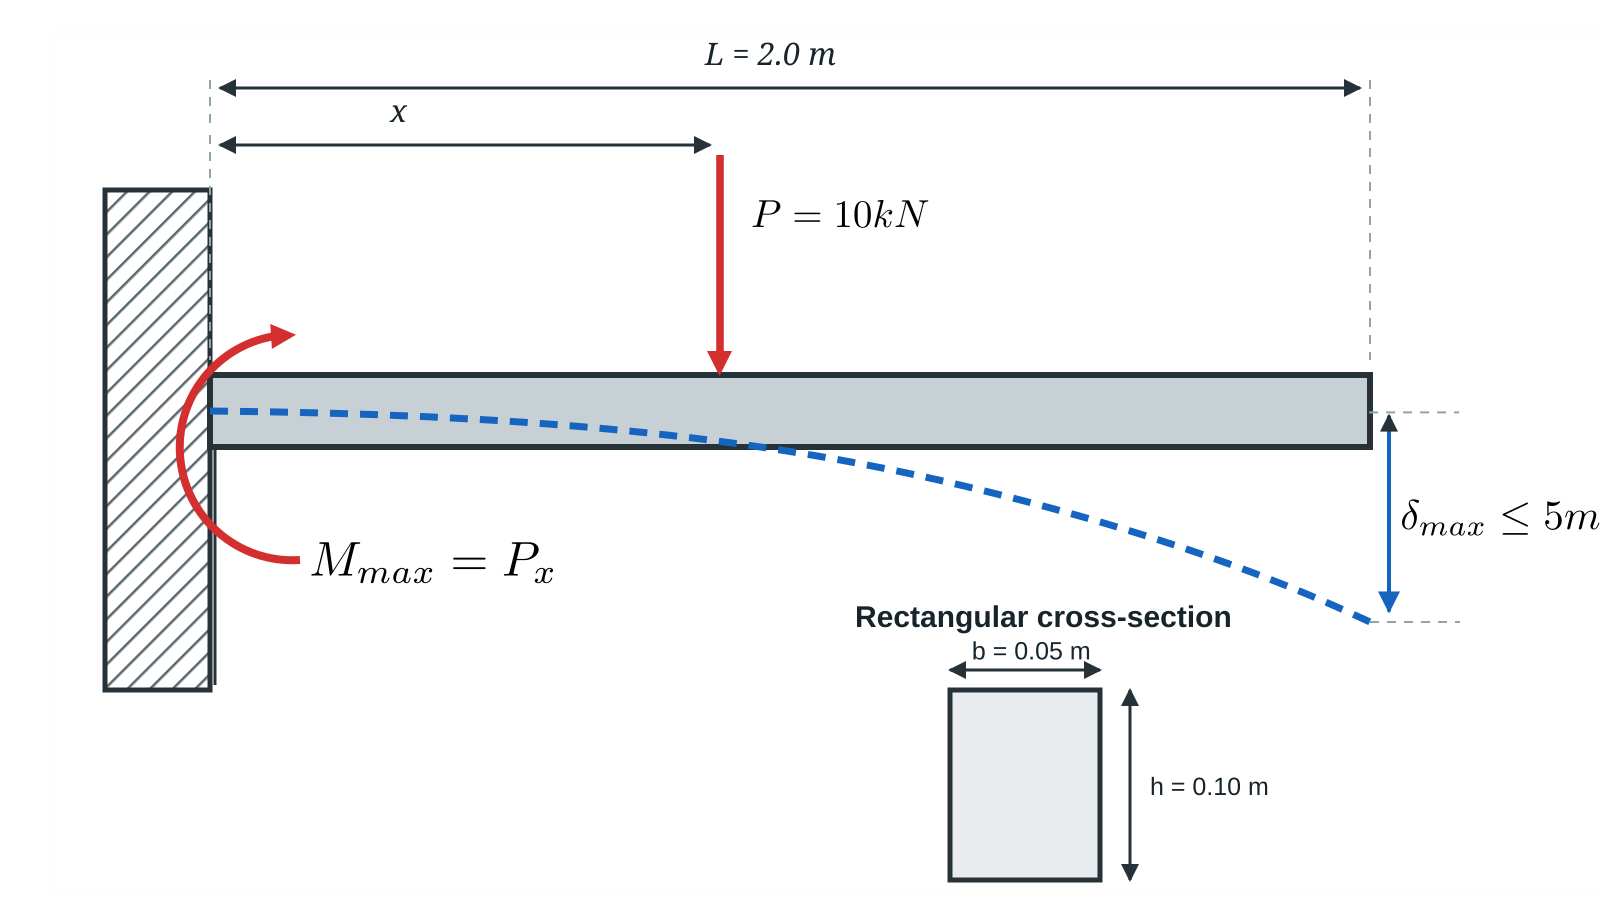
The position of the machine must satisfy three design requirements:

- The maximum bending stress at the fixed support must not exceed the allowable stress of the material.

- The maximum vertical deflection of the beam must not exceed the allowable deflection.

- The load position must, naturally, satisfy: 


$$$$
0\leq x\leq L.
$$$$


We provide further information on the properties of the beam and how to calculate maximum bending stress and maximum vertical deflection below. The questions of the problem are stated after that.


### Beam and material properties

The beam is made of steel and has a rectangular cross-section. Use the following properties:


### Cross-section properties

For a rectangular cross-section, the second moment of area about the neutral axis is


$$$$
I=\frac{bh^3}{12}
$$$$


The distance from the neutral axis to the outermost fibre is


$$$$
c=\frac{h}{2}
$$$$


### Stress constraint

For a concentrated load $$P$$ applied at a distance $$x$$ from the fixed support, the maximum bending moment occurs at the fixed support:

$$$
M_{\max}=Px
$$$.

The corresponding maximum bending stress is

$$$
\sigma_{\max}(x)
=
\frac{M_{\max}c}{I}
$$$.

The beam satisfies the stress requirement when


$$$$
\sigma_{\max}(x)
\leq
\sigma_{\mathrm{allow}}
$$$$


The maximum allowable position according to the stress constraint is denoted by $$$
x_{\max}
$$
$.

### Deflection constraint

The load is not necessarily applied at the free end of the beam. The beam continues from the load position $$x$
$ to the free end at $$L$$.

The vertical deflection at the load position is


$$$$
\delta_P(x)
=
\frac{Px^3}{3EI}
$$
$$


The free-end deflection is


$$$$
\delta_{\mathrm{tip}}(x)
=
\frac{Px^2(3L-x)}{6EI}

$$
$$


The beam satisfies the deflection requirement when

$$$
\delta_{\mathrm{max}}(x)
\leq
\delta_{\mathrm{allow}}
$$
$,

where $\delta_{\max}$ is the maximum deflection, which happens either at the load position or at the free-end.

### Safety factor


Define the safety factor against bending as


$$$$n=\frac{\sigma_{\mathrm{allow}}}{\sigma_{\max}}$$$$


### Problem 2: 

Complete the following tasks:

**a**. Determine the maximum distance $$x_{\max}$$ from the fixed support at which the force can be applied while satisfying all design requirements. Use root-finding methods and explain which method performs best. As before, explain in detail how the methods were used and generate convergence plots. Describe pros and cons of each method to motivate the best choice. ***(16 pts.)***

**b. **Identify which design requirement governs the maximum allowable position: beam length, allowable bending stress, or allowable deflection. Explain the physical meaning of the governing requirement. ***(5 pts.)***

**c. **Once you have identified the maximum position of the load, determine the safety factor. If it is less than 2, identify which cross-sectional area (width or height) should be modified and what its value should be to meet this requirement. ***(5 pts.)***

# Solution problem 2

#### Problem 2.a)

The bisection method was selected to determine the value of x_max for two reasons. Firstly, the problem indicates that the value of x_max falls within the domain (0, length). Additionally, the next guess of this method is not determined by the governing equations of the three primary criteria (stress, deflection at the point, & deflection at the tip) but by the selected interval itself, which allows all three criteria to be evauated in conjunction with one another instead of seperately.

In addition to the bisection method, the secant method is valid for approximating the point at which the deflection is approximately equal to the maximum deflection as well as the point at which the stress is approximately equal to the maximum stress; however, it require three seperate instances of the script to be run due to the inherently different relations which govern the selection of the next guess as well as the final root. This subsequently leads to higher computational costs. Additionally, due to the sensitivity to the initial guesses, the secant method is incapable of delivering consistent results and relies on good initial guesses in order to converge to the correct root.

After the roots are obtained, they can be compared and the smallets root can be selected.

Due to the nature of the problem, a unique version of the bisection method was specifically designed to account for both the stress and deflection values and generate convergence plots for the point (x), the engineering factor (n), and the deflection value (d) from their corresponding vectors.

In order to properly compare the behaviour of the custom bisection method script and the secant method, three seperate function calls are made to the secant method to evaulate the root to the problem for the stress experienced by the beam, the deflection at the point of evaluation, as well as the deflection at the tip.

### Bisection Method

% For reference, all lengths are in meters, the force is in kN, and the 
% values for the maximum stress and elastic modulus have been scaled down 
% by a factor of 1000 in order to maintain SI unit consistency throughout 
% the program.

function [a, xvec, nvec, dvec] = assignment1_prob2 (h, n_goal)
it = 1;
maxit = 20;
xvec = zeros(1, maxit);
nvec = zeros(1, maxit);
dvec = zeros(1, maxit);
tol = 0.0001;

L = 2;
l = 0;
u = L;
P = 10;
b = 0.05;
c = h/2;
I = (b*h^3)/12;
E = 200e9/1000;
stress_allowed = 150e6/1000;
deflection_max = 0.005;

while (u-l) > tol
    x = (l+u)/2;
    stress_actual = (P*x*c)/I;
    n = stress_allowed/stress_actual;

    deflection_at_point = (P*x^3)/(3*E*I);
    deflection_at_tip = (P*x^2*(3*L-x))/(6*E*I);
    deflection_max_actual = max(deflection_at_point, deflection_at_tip);

    if n >= n_goal && deflection_max_actual <= deflection_max
        l = x;    % stress and deflection at x are acceptable
    else
        u = x;    % stress and deflection at x are not acceptable
    end
    
    xvec(it) = x;
    nvec(it) = n;
    dvec(it) = deflection_max_actual;
    it = it + 1;
end

a = [x, n, deflection_max_actual];
xvec = xvec(xvec ~= 0)
nvec = nvec(nvec ~= 0)
dvec = dvec(dvec ~= 0)
 

xexact = xvec(end);
itvec = 0:(length(xvec)-1);
errvec = abs(xvec-xexact)/abs(xexact);
figure;
semilogy(itvec,errvec, '.-')
xlabel('Iteration number')
ylabel('Relative error |x_{k}-x^*|/|x^*|')
grid on

nexact = nvec(end);
itvec = 0:(length(nvec)-1);
errvec = abs(nvec-nexact)/abs(nexact);
figure;
semilogy(itvec,errvec, '.-')
xlabel('Iteration number')
ylabel('Relative error |n_{k}-n^*|/|n^*|')
grid on


dexact = dvec(end);
itvec = 0:(length(dvec)-1);
errvec = abs(dvec-dexact)/abs(dexact);
figure;
semilogy(itvec,errvec, '.-')
xlabel('Iteration number')
ylabel('Relative error |d_{k}-d^*|/|d^*|')
grid on

end

assignment1_prob2(0.1, 1)

### Secant Method

tol = 0.0001;
maxit = 20;
x0 = 0;
x1 = 0.5;
P = 10;
h = 0.1;
b = 0.05;
c = h/2;
L = 2;
I = (b*h^3)/12;
E = 200e9/1000;
stress_allowed = 150e6/1000;
deflection_max = 0.005;

stress_max = @(x) (P*x*c)/I - stress_allowed;
deflection_at_point = @(x) (P*x^3)/(3*E*I) - deflection_max;
deflection_at_tip = @(x) ((P*x^2)*(3*L-x))/(6*E*I) - deflection_max;

a = [0, 0, 0];

a(1) = secant_method(stress_max, x0, x1, maxit, tol)

a(2) = secant_method(deflection_at_point, x0, x1, maxit, tol)

a(3) = secant_method(deflection_at_tip, x0, x1, maxit, tol)

x = min(a)

Athough the secant function converges superlinearly and can be faster than the linear convergence of the bisection method, the necesity to call the function on three seperate ocassions and select the smallest distance value is inherently less convenient than evaluating the problem relative to all of its constraints. Additionally, with different initial guesses or value constraints, faster convergence is not guaranteed. 

For example, when evaluating the functions with an inital x1 guess of 0.5, the total number of iterations is 14, which is exactly equal to the number of iterations of the bisection method which are also 14; however, with an initial x1 guess of 0.1, the deflection at the point x never converges and creates absurd guesses for all 20 of its iterations and is only aborted by the maximum iteration constraint.

In essence, in addition to evaluating all of the relevant constraints in conjunction with one another, the bisection method is capable of delivering more consistent results than the secant method which makes it a significantly better solution to the problem.

#### Problem 2.b) 

The limiting design criteria is the maximum deflection at the tip of the beam. The load acting on the beam at point x displaces the beam from its starting neutral axis. Due to the geometry and arrangement of the beam and the point at which it is supported, the maximum deflection is always experienced at its tip. At the final point of evaluation, this deflection is approximately equal to the selected maximum deflection value.

#### Problem 2.c) 

Due to the properties of the area moment of inertia (I), the higher said value is, the lower the corresponding stress and deflection become.

By evaluating its governing equation I = (b*h^3)/12, we can clearly see that an increase in the value of the height of the beam is significantly more capable at reducing the stress and deflection experienced by the beam than an identical modification to its width.

The outputted x value of the function used for problem 2.a) is taken via a(1) and used to calculate an approximate solution to the required additional height of the beam in order to satisfy the condition n>=2 at the specified point. Since the condition for the maximum deflection is already satisfied, and the only term which needs to be modified is the height of the beam, we can find the solution by isolating the height form the other terms.

In order to solve for the height of the beam, we must firstly expand stress_actual into its full form: 

% stress_actual = ((P*x*(h/2))/((b*h^3)/12)).

Afterwards, we can simplify this expression to:

% 6*(P*x)/(b*h^2)

Now that we have a expanded and simplified expression for the stress experienced by the beam, we can set:

% stress_allowed/(6*(P*x)/(b*h^2)) = 2

Afterwards, both sides are multiplied by the numerator on the left to produce:

% stress_allowed = 12*(P*x)/(b*h^2).

Finally, both sides are multiplied by h^2, divided by stress_allowed, and then the square root of both sides is taken, isolating the expression which satisfies the safety factor condition in terms of h:

% h_new = sqrt((12*P*a(1)/(b*stress_allowed)))

Now that we have obtained a value for h which satisfies our engineering safety factor we can also determine the cross-sectional area of the beam and compare it to its original cross-sectional area:

% old_area = h*b
% new_area = h_new*b
% percent_increase_in_area = 1 - new_area/old_area

Finally, we can confirm whether this new height satisfies both the deflection and engineering safety factors by running the function applied in 2.a) again with the new height and n = 2.

% 2.c)
P = 10;
x = 0.6859;
b = 0.05;
h = 0.1;
stress_allowed = 150e6/1000;
h_new = sqrt((12*P*x/(b*stress_allowed)))

old_area = h*b
new_area = h_new*b
percent_increase_in_area = 100 * ((new_area-old_area)/old_area)

assignment1_prob2(h_new, 2)

This second function call confirms that with the modifications that have been made to the height of the beam, the point at which n = 2 is the exact same point (x) which was solved for on the first calling of the function with the original height and n = 1.

## Problem 3: Outlet Temperatures of a Counter-Flow Heat Exchanger (logarithmic mean temperature difference -LMTD) ***(22 pts.)***

## Problem description

A counter-flow heat exchanger is used to heat water using hot oil. The two fluids flow in opposite directions and do not mix (see [https://www.youtube.com/watch?v=NvkZaWLe0Sk](https://www.youtube.com/watch?v=NvkZaWLe0Sk) for an explanation of the device). A simple counter-flow heat exchanger is shown in the below figure:

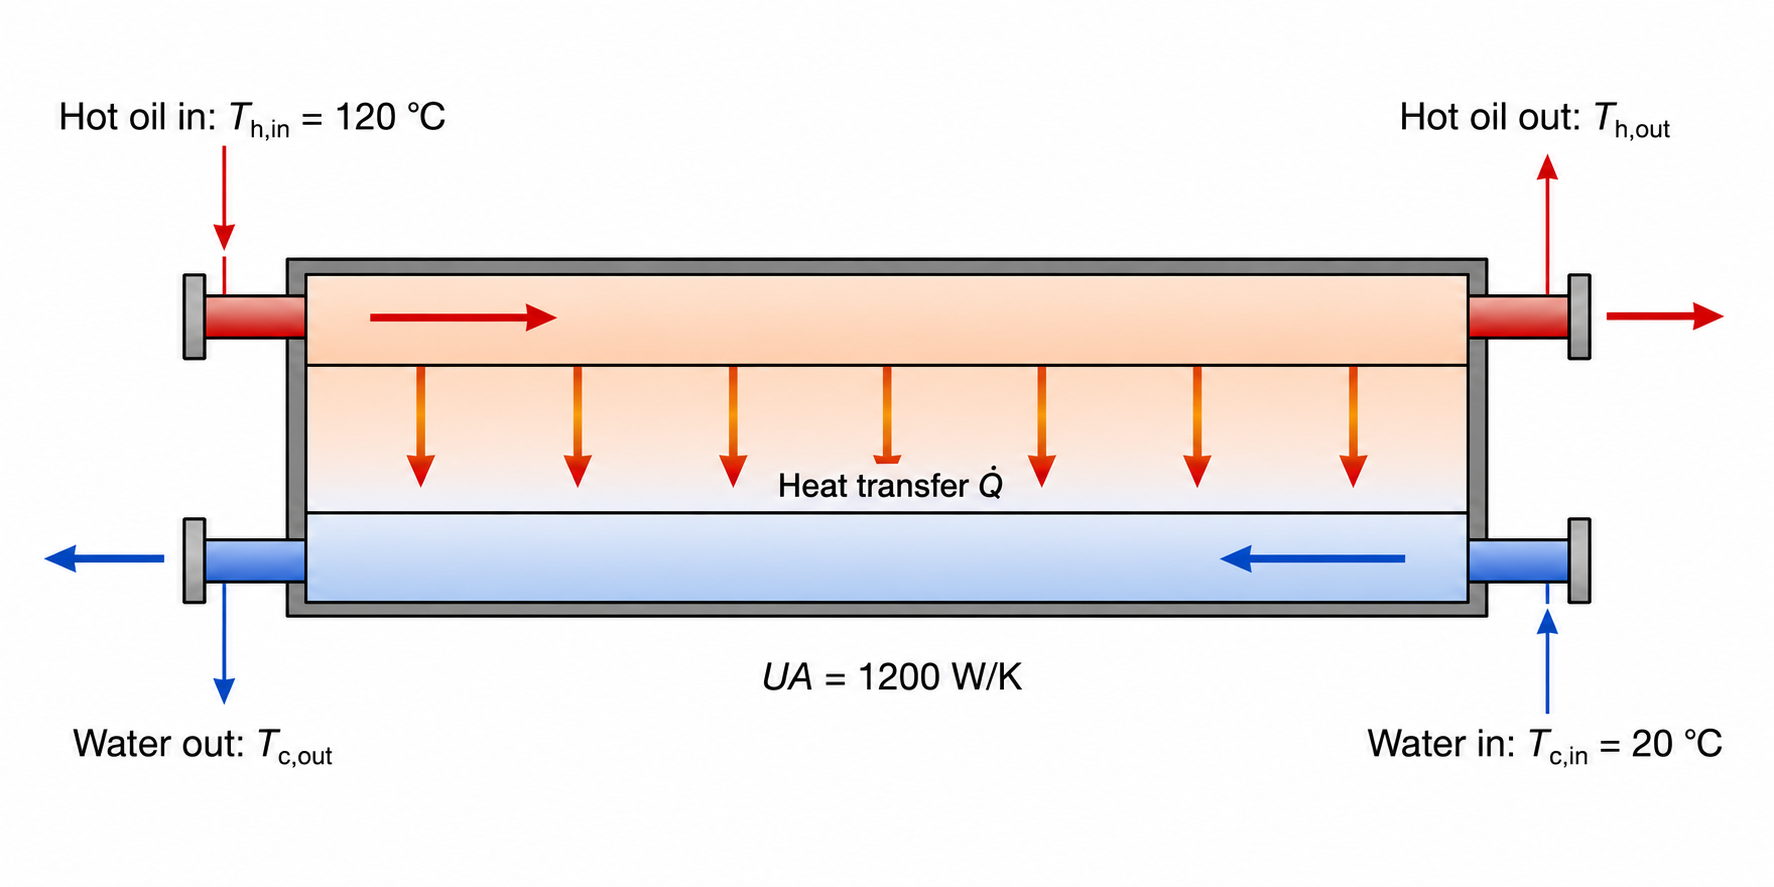

The inlet temperatures, mass flow rates, specific heat capacities, and overall thermal conductance of the heat exchanger are known. However, the outlet temperatures and the heat-transfer rate are unknown.

The goal of this problem is to determine ***(6 pts)***:

-  The outlet temperature of the water

- The outlet temperature of the oil

- The heat-transfer rate between the fluids

Explain the process and methodology, developing the energy balance, applying all the root-finding methods studied in lectures, and comparing their convergence rates and errors to assess robustness. Again, be sure to motivate and lay-out clearly all decisions you make ***(16 pts.)***

The necessary information to solve this problem is below.

## Problem variables

Use the following input values for the particular case:

The heat capacities are representative constant values for liquid water and a typical heat-transfer oil.

The subscripts have the following meanings:

- $$o$$: oil

- $$w$$: water

- $$\mathrm{in}$$: inlet

- $$\mathrm{out}$$: outlet

## Modeling assumptions

Assume that:

- The heat exchanger operates under steady-state conditions

- There is no heat loss to the surroundings

- The two fluids do not mix

- The specific heat capacities remain constant

- There is no phase change

- Kinetic- and potential-energy changes are negligible

- The overall heat-transfer coefficient is constant

- The heat exchanger operates in counter-flow

Because there is no heat loss to the surroundings, the heat lost by the oil is equal to the heat gained by the water.

## Heat-capacity rates

For each fluid, define the heat-capacity rate as


$$$$
C=\dot m c_p
$$$$


For the oil,


$$$$
{
C_o=\dot m_oc_{p,o}
}
$$$$


and for the water,


$$$$
C_w=\dot m_wc_{p,w}
}
$$$$


The units of a heat-capacity rate are


$$$$
[C]
=
\frac{\mathrm{kg}}{\mathrm{s}}
\frac{\mathrm{J}}{\mathrm{kg\,K}}
=
\frac{\mathrm{W}}{\mathrm{K}}
$$$$


The heat-capacity rate indicates the amount of heat-transfer power required to change the fluid temperature by one kelvin.

## Mathematical setup

The solution must satisfy the energy balance

$$$\dot Q=C_w(T_{w,\mathrm{out}}-T_{w,\mathrm{in}})=C_o(T_{o,\mathrm{in}}-T_{o,\mathrm{out}})$$$,

where $\dot{Q}$ is the heat-transfer rate.

For counter-flow operation, the terminal temperature differences are


$$$$\Delta T_1=T_{o,\mathrm{in}}-T_{w,\mathrm{out}}, \qquad \Delta T_2=T_{o,\mathrm{out}}-T_{w,\mathrm{in}}$$$$


The logarithmic mean temperature difference and exchanger heat-transfer equation are


$$$$\Delta T_{\mathrm{lm}}=\frac{\Delta T_1-\Delta T_2}{\ln(\Delta T_1/\Delta T_2)}, \qquad \dot Q=UA\Delta T_{\mathrm{lm}}$$$$


These equations contain the two unknowns $$T_{w,\mathrm{out}}$ \text{ and } $T_{o,\mathrm{out}}$$. To be able to determine them both, first rewrite the equations so that there exists a single equation with one unknown. Then apply a root-finding method.

# Solution problem 3

*Add your solution here using written text, equations, and blocks of code.*